clc;
clear;
close all;

%% ========================================================
% STEP 7: FINAL RESULTS AND VALIDATION
%
% This step ONLY loads the results produced by Steps 1-6.
%
% No trajectory generation
% No sensor generation
% No VIO
% No controller
% No drone dynamics
%
% It evaluates the complete toy model.
% ========================================================


%% --------------------------------------------------------
% 1. Load complete project data
% ---------------------------------------------------------

load('drone_toy_model.mat');



%% --------------------------------------------------------
% 2. Check required variables
% ---------------------------------------------------------

requiredVariables = {
    't'
    'dt'
    'waypoints'
    'waypointTime'
    'pd'
    'vd'
    'ad'
    'p_camera'
    'p_est_history'
    'v_est_history'
    'R_est_history'
    'desired_thrust'
    'torque_command'
    'R_desired_history'
    'p_history'
    'v_history'
    'R_history'
    'omega_history'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error(['Missing variable: ', ...
               requiredVariables{i}, ...
               '. Run the previous step first.']);

    end

end


numSamples = length(t);



%% ========================================================
% PART A: TRAJECTORY GENERATION RESULTS
% =========================================================


%% --------------------------------------------------------
% 3. Reference trajectory statistics
% ---------------------------------------------------------

trajectory_distance = 0;

for k = 1:numSamples-1

    trajectory_distance = ...
        trajectory_distance + ...
        norm(pd(k+1,:) - pd(k,:));

end

maximum_speed = ...
    max(vecnorm(vd,2,2));

maximum_acceleration = ...
    max(vecnorm(ad,2,2));


%% ========================================================
% PART B: VIO / STATE ESTIMATION RESULTS
% =========================================================


%% --------------------------------------------------------
% 4. Position estimation error
% ---------------------------------------------------------

vio_position_error = ...
    p_est_history - pd;

vio_position_RMSE = ...
    sqrt(mean(vio_position_error.^2,1));

vio_position_error_norm = ...
    vecnorm(vio_position_error,2,2);

vio_position_max_error = ...
    max(vio_position_error_norm);


%% --------------------------------------------------------
% 5. Velocity estimation error
% ---------------------------------------------------------

vio_velocity_error = ...
    v_est_history - vd;

vio_velocity_RMSE = ...
    sqrt(mean(vio_velocity_error.^2,1));


%% --------------------------------------------------------
% 6. Camera measurement error
% ---------------------------------------------------------

camera_error = ...
    p_camera - pd;

camera_RMSE = ...
    sqrt(mean(camera_error.^2,1));

camera_error_norm = ...
    vecnorm(camera_error,2,2);


%% --------------------------------------------------------
% 7. Attitude estimation error
%
% R_error = R_true^T R_est
% =========================================================

if exist('R_true','var')

    vio_attitude_error = ...
        zeros(numSamples,1);

    for k = 1:numSamples

        R_error = ...
            R_true(:,:,k)' * ...
            R_est_history(:,:,k);

        theta = ...
            acos( ...
                max(-1,min(1, ...
                (trace(R_error)-1)/2)));

        vio_attitude_error(k) = theta;

    end

    vio_attitude_RMSE = ...
        sqrt(mean(vio_attitude_error.^2));

else

    vio_attitude_error = [];
    vio_attitude_RMSE = NaN;

end



%% ========================================================
% PART C: CONTROLLER RESULTS
% =========================================================


%% --------------------------------------------------------
% 8. Thrust statistics
% ---------------------------------------------------------

maximum_thrust = ...
    max(desired_thrust);

minimum_thrust = ...
    min(desired_thrust);

average_thrust = ...
    mean(desired_thrust);


%% --------------------------------------------------------
% 9. Torque statistics
% ---------------------------------------------------------

maximum_torque = ...
    max(abs(torque_command),[],1);

RMS_torque = ...
    sqrt(mean(torque_command.^2,1));


%% --------------------------------------------------------
% 10. Controller position error
% ---------------------------------------------------------

controller_position_error = ...
    pd - p_est_history;

controller_position_RMSE = ...
    sqrt(mean(controller_position_error.^2,1));


%% ========================================================
% PART D: ACTUAL DRONE TRACKING RESULTS
% =========================================================


%% --------------------------------------------------------
% 11. Actual position tracking error
%
% e_p = p_d - p_actual
% ---------------------------------------------------------

position_tracking_error = ...
    pd - p_history;

position_tracking_RMSE = ...
    sqrt(mean(position_tracking_error.^2,1));

position_tracking_error_norm = ...
    vecnorm(position_tracking_error,2,2);

maximum_position_tracking_error = ...
    max(position_tracking_error_norm);

final_position_tracking_error = ...
    position_tracking_error_norm(end);


%% --------------------------------------------------------
% 12. Actual velocity tracking error
% ---------------------------------------------------------

velocity_tracking_error = ...
    vd - v_history;

velocity_tracking_RMSE = ...
    sqrt(mean(velocity_tracking_error.^2,1));



%% --------------------------------------------------------
% 13. Actual attitude tracking error
%
% R_error = R_d^T R
% ---------------------------------------------------------

attitude_tracking_error = ...
    zeros(numSamples,1);

attitude_tracking_vector = ...
    zeros(numSamples,3);

for k = 1:numSamples

    Rd = ...
        R_desired_history(:,:,k);

    R_actual = ...
        R_history(:,:,k);

    R_error = ...
        Rd' * R_actual;

    theta = ...
        acos( ...
            max(-1,min(1, ...
            (trace(R_error)-1)/2)));

    attitude_tracking_error(k) = ...
        theta;

    %% SO(3) vector error

    if theta < 1e-8

        attitude_tracking_vector(k,:) = ...
            [0 0 0];

    else

        attitude_axis = ...
            (1/(2*sin(theta))) * ...
            [
                R_error(3,2)-R_error(2,3);
                R_error(1,3)-R_error(3,1);
                R_error(2,1)-R_error(1,2)
            ];

        attitude_tracking_vector(k,:) = ...
            (theta*attitude_axis)';

    end

end


attitude_tracking_RMSE = ...
    sqrt(mean(attitude_tracking_error.^2));


%% ========================================================
% PART E: PHYSICAL VALIDATION
% =========================================================


%% --------------------------------------------------------
% 14. Rotation matrix validity
% ---------------------------------------------------------

rotation_orthogonality_error = ...
    zeros(numSamples,1);

rotation_determinant_error = ...
    zeros(numSamples,1);

for k = 1:numSamples

    Rk = ...
        R_history(:,:,k);

    rotation_orthogonality_error(k) = ...
        norm(Rk'*Rk-eye(3),'fro');

    rotation_determinant_error(k) = ...
        abs(det(Rk)-1);

end


maximum_orthogonality_error = ...
    max(rotation_orthogonality_error);

maximum_determinant_error = ...
    max(rotation_determinant_error);


%% --------------------------------------------------------
% 15. Hover thrust reference
% ---------------------------------------------------------

m = 1.0;

g_magnitude = 9.81;

hover_thrust = ...
    m*g_magnitude;

thrust_deviation = ...
    desired_thrust - hover_thrust;


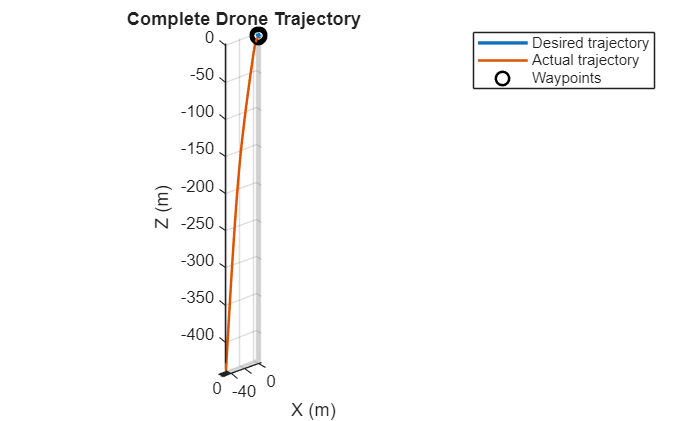


%% ========================================================
% PART F: FINAL PLOTS
% =========================================================


%% --------------------------------------------------------
% 16. Complete trajectory
% ---------------------------------------------------------

figure;

plot3( ...
    pd(:,1), ...
    pd(:,2), ...
    pd(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_history(:,1), ...
    p_history(:,2), ...
    p_history(:,3), ...
    'LineWidth',1.5);

plot3( ...
    waypoints(:,1), ...
    waypoints(:,2), ...
    waypoints(:,3), ...
    'ko', ...
    'MarkerSize',8, ...
    'LineWidth',1.5);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Complete Drone Trajectory');

legend( ...
    'Desired trajectory', ...
    'Actual trajectory', ...
    'Waypoints');

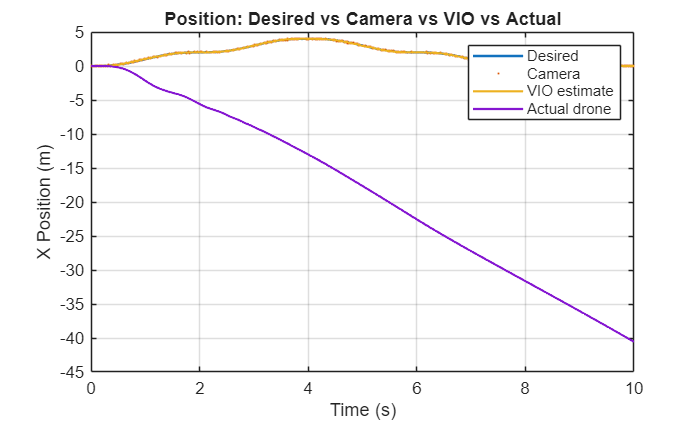



%% --------------------------------------------------------
% 17. Camera vs VIO vs actual
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    pd(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    p_camera(:,1), ...
    '.', ...
    'MarkerSize',3);

plot( ...
    t, ...
    p_est_history(:,1), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    p_history(:,1), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('X Position (m)');

title('Position: Desired vs Camera vs VIO vs Actual');

legend( ...
    'Desired', ...
    'Camera', ...
    'VIO estimate', ...
    'Actual drone');

grid on;

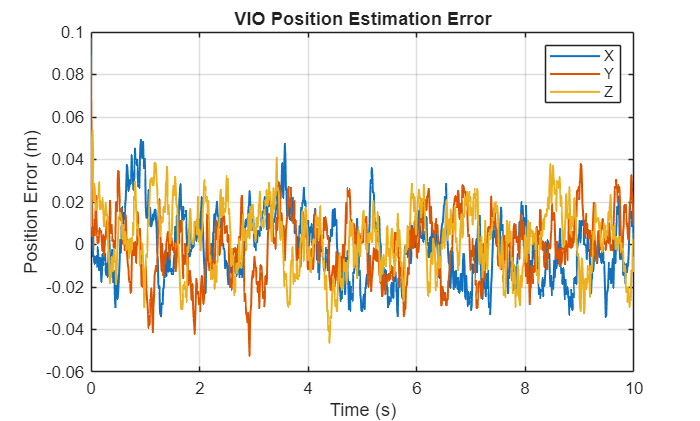



%% --------------------------------------------------------
% 18. VIO position estimation error
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    vio_position_error(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    vio_position_error(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    vio_position_error(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('VIO Position Estimation Error');

legend('X','Y','Z');

grid on;

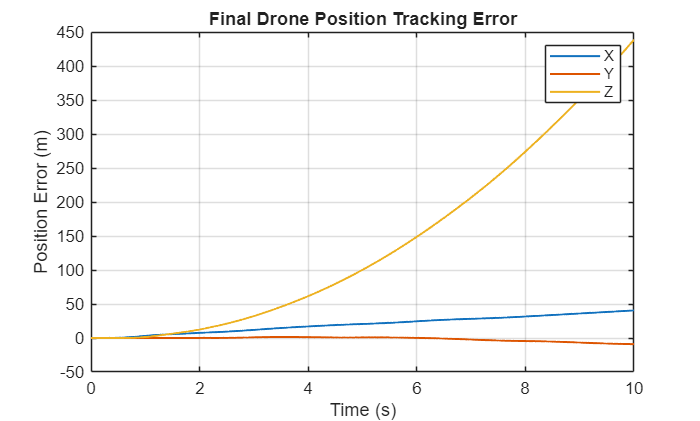



%% --------------------------------------------------------
% 19. Actual position tracking error
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    position_tracking_error(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    position_tracking_error(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    position_tracking_error(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('Final Drone Position Tracking Error');

legend('X','Y','Z');

grid on;

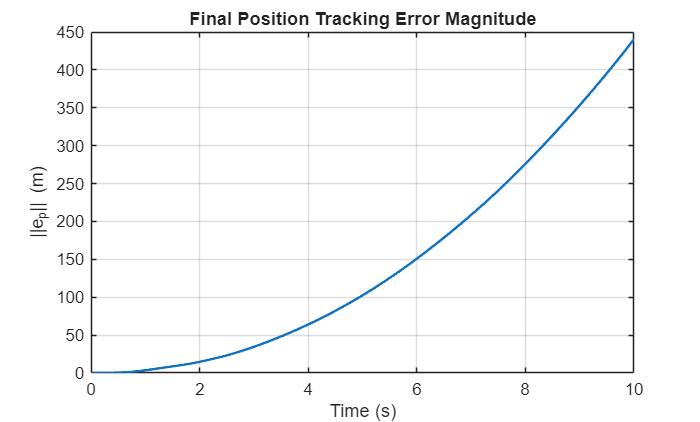



%% --------------------------------------------------------
% 20. Position error magnitude
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    position_tracking_error_norm, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('||e_p|| (m)');

title('Final Position Tracking Error Magnitude');

grid on;

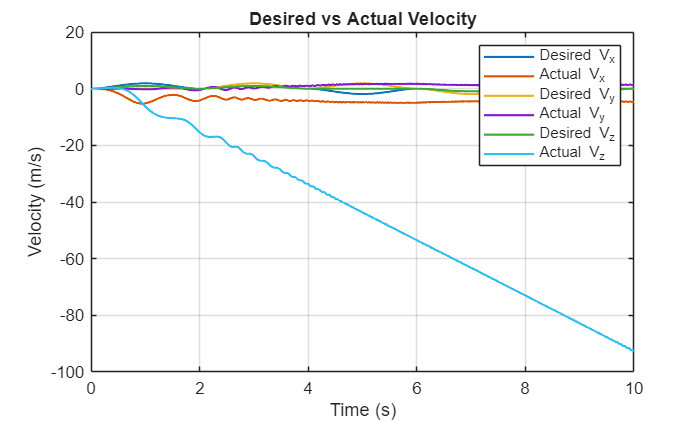



%% --------------------------------------------------------
% 21. Desired vs actual velocity
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    vd(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    v_history(:,1), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    vd(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    vd(:,3), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Velocity (m/s)');

title('Desired vs Actual Velocity');

legend( ...
    'Desired V_x', ...
    'Actual V_x', ...
    'Desired V_y', ...
    'Actual V_y', ...
    'Desired V_z', ...
    'Actual V_z');

grid on;

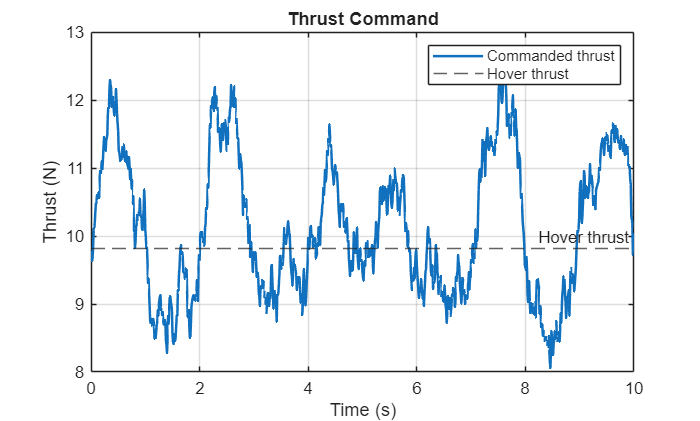


%% --------------------------------------------------------
% 22. Thrust
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    desired_thrust, ...
    'LineWidth',1.5);

hold on;

yline( ...
    hover_thrust, ...
    '--', ...
    'Hover thrust');

xlabel('Time (s)');
ylabel('Thrust (N)');

title('Thrust Command');

legend( ...
    'Commanded thrust', ...
    'Hover thrust');

grid on;

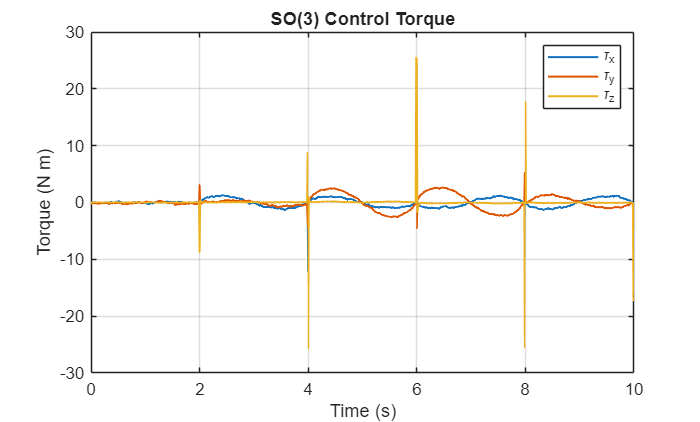



%% --------------------------------------------------------
% 23. Torque
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    torque_command(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    torque_command(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    torque_command(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Torque (N m)');

title('SO(3) Control Torque');

legend( ...
    '\tau_x', ...
    '\tau_y', ...
    '\tau_z');

grid on;

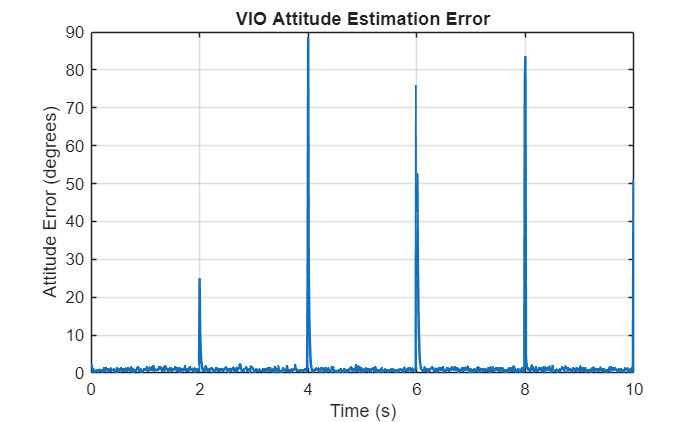


%% --------------------------------------------------------
% 24. VIO attitude estimation error
% ---------------------------------------------------------

if ~isempty(vio_attitude_error)

    figure;

    plot( ...
        t, ...
        rad2deg(vio_attitude_error), ...
        'LineWidth',1.5);

    xlabel('Time (s)');
    ylabel('Attitude Error (degrees)');

    title('VIO Attitude Estimation Error');

    grid on;

end

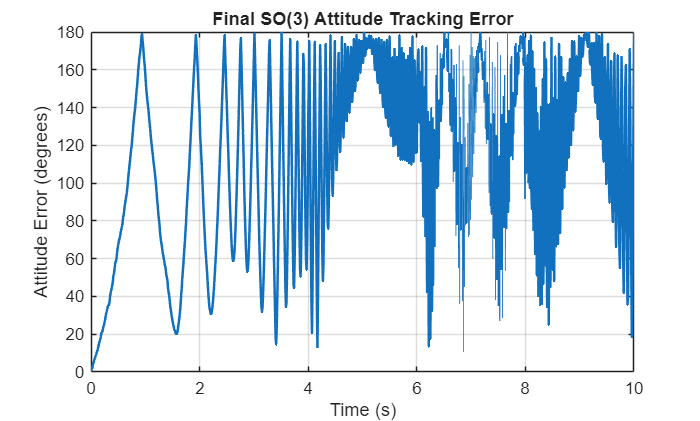



%% --------------------------------------------------------
% 25. Final attitude tracking error
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    rad2deg(attitude_tracking_error), ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Attitude Error (degrees)');

title('Final SO(3) Attitude Tracking Error');

grid on;

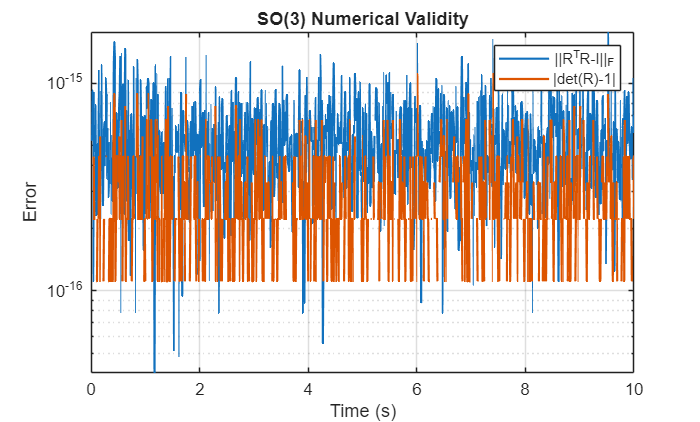



%% --------------------------------------------------------
% 26. SO(3) validity
% ---------------------------------------------------------

figure;

semilogy( ...
    t, ...
    rotation_orthogonality_error, ...
    'LineWidth',1.3);

hold on;

semilogy( ...
    t, ...
    rotation_determinant_error, ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Error');

title('SO(3) Numerical Validity');

legend( ...
    '||R^TR-I||_F', ...
    '|det(R)-1|');

grid on;



%% ========================================================
% PART G: FINAL NUMERICAL SUMMARY
% =========================================================


fprintf('\n');
fprintf('========================================================\n');

fprintf('           COMPLETE DRONE TOY MODEL RESULTS\n');

           COMPLETE DRONE TOY MODEL RESULTS


fprintf('========================================================\n');



%% --------------------------------------------------------
% Trajectory
% ---------------------------------------------------------

fprintf('\nTRAJECTORY\n');


TRAJECTORY


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Total trajectory distance = %.4f m\n', ...
    trajectory_distance);

Total trajectory distance = 13.3006 m



fprintf( ...
    'Maximum desired speed     = %.4f m/s\n', ...
    maximum_speed);

Maximum desired speed     = 2.8125 m/s



fprintf( ...
    'Maximum desired accel.    = %.4f m/s^2\n', ...
    maximum_acceleration);

Maximum desired accel.    = 4.3300 m/s^2




%% --------------------------------------------------------
% Camera
% ---------------------------------------------------------

fprintf('\nCAMERA MEASUREMENT\n');


CAMERA MEASUREMENT


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Camera position RMSE X = %.4f m\n', ...
    camera_RMSE(1));

Camera position RMSE X = 0.0490 m



fprintf( ...
    'Camera position RMSE Y = %.4f m\n', ...
    camera_RMSE(2));

Camera position RMSE Y = 0.0485 m



fprintf( ...
    'Camera position RMSE Z = %.4f m\n', ...
    camera_RMSE(3));

Camera position RMSE Z = 0.0497 m




%% --------------------------------------------------------
% VIO
% ---------------------------------------------------------

fprintf('\nVIO / STATE ESTIMATION\n');


VIO / STATE ESTIMATION


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'VIO position RMSE X = %.4f m\n', ...
    vio_position_RMSE(1));

VIO position RMSE X = 0.0162 m



fprintf( ...
    'VIO position RMSE Y = %.4f m\n', ...
    vio_position_RMSE(2));

VIO position RMSE Y = 0.0146 m



fprintf( ...
    'VIO position RMSE Z = %.4f m\n', ...
    vio_position_RMSE(3));

VIO position RMSE Z = 0.0156 m



fprintf( ...
    'Maximum VIO position error = %.4f m\n', ...
    vio_position_max_error);

Maximum VIO position error = 0.1321 m



fprintf( ...
    'VIO velocity RMSE X = %.4f m/s\n', ...
    vio_velocity_RMSE(1));

VIO velocity RMSE X = 0.0618 m/s



fprintf( ...
    'VIO velocity RMSE Y = %.4f m/s\n', ...
    vio_velocity_RMSE(2));

VIO velocity RMSE Y = 0.0618 m/s



fprintf( ...
    'VIO velocity RMSE Z = %.4f m/s\n', ...
    vio_velocity_RMSE(3));

VIO velocity RMSE Z = 0.0645 m/s



if ~isnan(vio_attitude_RMSE)

    fprintf( ...
        'VIO attitude RMSE = %.4f deg\n', ...
        rad2deg(vio_attitude_RMSE));

end

VIO attitude RMSE = 6.2473 deg




%% --------------------------------------------------------
% Controller
% ---------------------------------------------------------

fprintf('\nSO(3) CONTROLLER\n');


SO(3) CONTROLLER


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Maximum thrust = %.4f N\n', ...
    maximum_thrust);

Maximum thrust = 12.6355 N



fprintf( ...
    'Minimum thrust = %.4f N\n', ...
    minimum_thrust);

Minimum thrust = 8.0575 N



fprintf( ...
    'Average thrust = %.4f N\n', ...
    average_thrust);

Average thrust = 10.1351 N



fprintf( ...
    'Maximum |tau_x| = %.4f N m\n', ...
    maximum_torque(1));

Maximum |tau_x| = 12.1098 N m



fprintf( ...
    'Maximum |tau_y| = %.4f N m\n', ...
    maximum_torque(2));

Maximum |tau_y| = 5.2133 N m



fprintf( ...
    'Maximum |tau_z| = %.4f N m\n', ...
    maximum_torque(3));

Maximum |tau_z| = 25.5660 N m




%% --------------------------------------------------------
% Actual drone
% ---------------------------------------------------------

fprintf('\nACTUAL DRONE TRACKING\n');


ACTUAL DRONE TRACKING


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Position RMSE X = %.4f m\n', ...
    position_tracking_RMSE(1));

Position RMSE X = 23.2796 m



fprintf( ...
    'Position RMSE Y = %.4f m\n', ...
    position_tracking_RMSE(2));

Position RMSE Y = 3.3568 m



fprintf( ...
    'Position RMSE Z = %.4f m\n', ...
    position_tracking_RMSE(3));

Position RMSE Z = 191.9852 m



fprintf( ...
    'Maximum position error = %.4f m\n', ...
    maximum_position_tracking_error);

Maximum position error = 440.6262 m



fprintf( ...
    'Final position error = %.4f m\n', ...
    final_position_tracking_error);

Final position error = 440.6262 m



fprintf( ...
    'Velocity RMSE X = %.4f m/s\n', ...
    velocity_tracking_RMSE(1));

Velocity RMSE X = 4.2287 m/s



fprintf( ...
    'Velocity RMSE Y = %.4f m/s\n', ...
    velocity_tracking_RMSE(2));

Velocity RMSE Y = 1.6207 m/s



fprintf( ...
    'Velocity RMSE Z = %.4f m/s\n', ...
    velocity_tracking_RMSE(3));

Velocity RMSE Z = 51.8082 m/s



fprintf( ...
    'Attitude tracking RMSE = %.4f deg\n', ...
    rad2deg(attitude_tracking_RMSE));

Attitude tracking RMSE = 124.1030 deg




%% --------------------------------------------------------
% Physical validity
% ---------------------------------------------------------

fprintf('\nPHYSICAL / MATHEMATICAL VALIDATION\n');


PHYSICAL / MATHEMATICAL VALIDATION


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf( ...
    'Hover thrust = %.4f N\n', ...
    hover_thrust);

Hover thrust = 9.8100 N



fprintf( ...
    'Maximum SO(3) orthogonality error = %.4e\n', ...
    maximum_orthogonality_error);

Maximum SO(3) orthogonality error = 1.7668e-15



fprintf( ...
    'Maximum SO(3) determinant error = %.4e\n', ...
    maximum_determinant_error);

Maximum SO(3) determinant error = 1.1102e-15




fprintf('\n========================================================\n');

fprintf('                 STEP 7 COMPLETE\n');

                 STEP 7 COMPLETE


fprintf('========================================================\n');



%% ========================================================
% 27. Save final results
% =========================================================

save( ...
    'drone_toy_model.mat', ...
    'trajectory_distance', ...
    'maximum_speed', ...
    'maximum_acceleration', ...
    'camera_RMSE', ...
    'vio_position_error', ...
    'vio_position_RMSE', ...
    'vio_position_error_norm', ...
    'vio_position_max_error', ...
    'vio_velocity_error', ...
    'vio_velocity_RMSE', ...
    'vio_attitude_error', ...
    'vio_attitude_RMSE', ...
    'maximum_thrust', ...
    'minimum_thrust', ...
    'average_thrust', ...
    'maximum_torque', ...
    'RMS_torque', ...
    'position_tracking_error', ...
    'position_tracking_RMSE', ...
    'position_tracking_error_norm', ...
    'maximum_position_tracking_error', ...
    'final_position_tracking_error', ...
    'velocity_tracking_error', ...
    'velocity_tracking_RMSE', ...
    'attitude_tracking_error', ...
    'attitude_tracking_vector', ...
    'attitude_tracking_RMSE', ...
    'hover_thrust', ...
    'thrust_deviation', ...
    'rotation_orthogonality_error', ...
    'rotation_determinant_error');

fprintf('\nFinal results saved to drone_toy_model.mat\n');


Final results saved to drone_toy_model.mat
